**Nome: Guilherme Tsubahara Horstmann e Marcos Davi de Oliveira**

## **Laboratório de ISC: Reposta ao Sistema de 1ª Ordem**

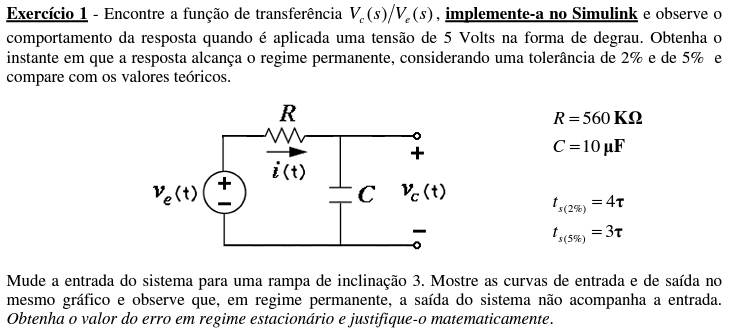

Analisando o circuito elétrico da figura acima, para encontrarmos a função transferencia, podemos utilizar a lei de Kirchhoff das tensões no domínio da frequência:


$$-V_e +\mathit{RI}+\frac{1}{\mathit{sC}}I=0\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;V_c =\frac{I}{\mathrm{sC}}\to I={\mathrm{sCV}}_c$$



$$-V_e +{\mathit{sCRV}}_e +V_c =0\to V_c \left(\mathit{sCR}+1\right)=V_e \to \frac{V_c \left(s\right)}{V_e \left(s\right)}=\frac{1}{\mathit{sCR}+1}=\frac{1}{\mathit{RC}}\frac{1}{s+\frac{1}{\mathit{RC}}}$$


Logo, a equação final é:


$$\frac{V_c \left(s\right)}{V_e \left(s\right)}=\frac{\frac{1}{\mathit{RC}}}{s+\frac{1}{\mathit{RC}}}=\frac{178,57m}{s+178,57m}$$


Além disso, também temos:


$$\begin{array}{l}
\tau =\frac{1}{a}=\frac{1}{178,57m}=5,60\\
T_s \left(2%\right)=4\tau \;=22,40s\\
T_s \left(5%\right)=3\tau \;=16,80s
\end{array}$$


Em seguida, criarmos o esquemático no simulink.

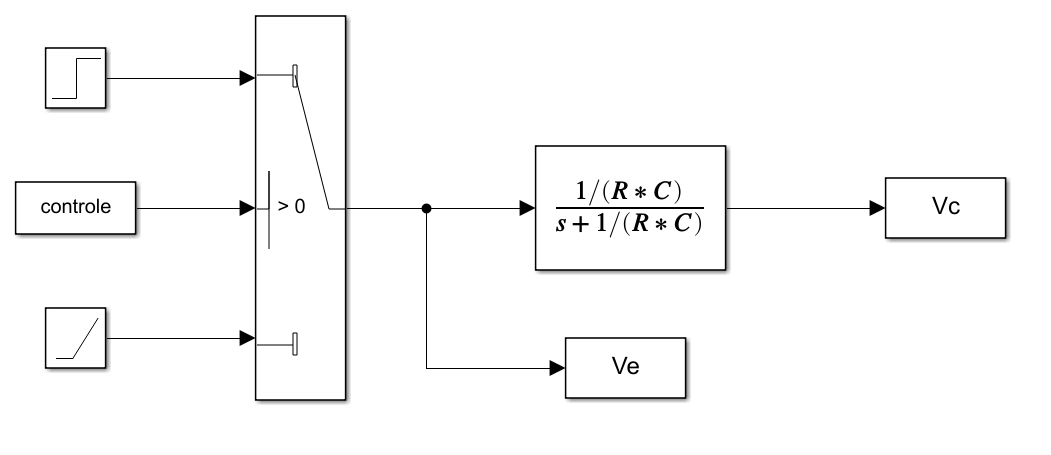

Feito isso, simulamos e plotamos os gráficos:

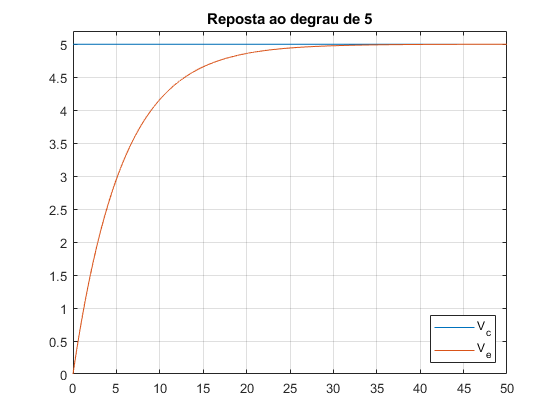

clc;
close all;
clear all;


R = 560e3;
C = 10e-6;
% se controle > 0 -> degrau
% se controle < 0 -> rampa

% para degrau = 1
controle = 1;
sim('exercicio1');
plot(t,Ve,t,Vc)
legend('V_c', 'V_e','location','southeast');
title('Reposta ao degrau de 5')
axis([-inf +inf 0 5.2]);
grid on;

valor_final = Vc(50000);

Vs2 = Vc(50000)-Vc(50000)*2/100;
Ts2 = 21.54;
Vs5 = Vc(50000)-Vc(50000)*5/100;
Ts5 =16.93;

Ao analisarmos o gráfico temos:


$$\begin{array}{l}
T_s \left(2%\right)=21,54s\\
T_s \left(5%\right)=16,93s
\end{array}$$


Logo, podemos comparar os valores teóricos com os simulados:


$$\left\lbrack \begin{array}{ccc}
 & \mathrm{Teórico} & \mathrm{Simulado}\\
T_s \left(2%\right) & 22\ldotp 40 & 21\ldotp 54\\
T_s \left(5%\right) & 16\ldotp 80 & 16\ldotp 93
\end{array}\right\rbrack$$


Se analisarmos a tabela acima, é possível perceber a convegência dos valores teórico e simulados.

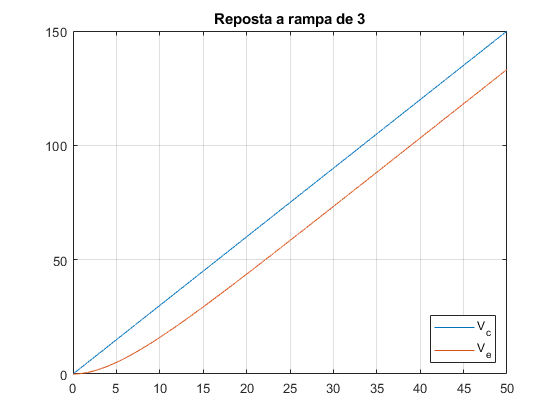

% para rampa = 3
controle = -1;
b = 3;
sim('exercicio1');
plot(t,Ve,t,Vc)
legend('V_c', 'V_e','location','southeast');
title('Reposta a rampa de 3')
axis([-inf +inf 0 +inf]);
grid on;

ed = Ve(end)-Vc(end)
t_exp = ed/b

Ao analisarmos o gráfico acima, podemos encontrar o valor de $\tau$:


$$\tau =\frac{e_d }{b}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;e_d =16,7978$$



$$\tau =\frac{16,7978}{3}=5,5993$$


Assim podemos comparar o $\tau \;$analítico com o encontrado na resposta a rampa de 3.


$$\left\lbrack \begin{array}{ccc}
 & \mathrm{Teórico} & \mathrm{Simulado}\\
\tau \; & 5\ldotp 6000 & 5\ldotp 5993
\end{array}\right\rbrack$$


Podemos dessa maneira, calcular o erro percentual.


$$E_% =\frac{|\tau {\;}_{\mathrm{teó}} -\tau {\;}_{\mathrm{exp}} |}{\tau_{\mathrm{teó}} \;}\times 100=0,01%$$


Assim, podemos perceber que o erro é ínfimo e podemos considerar o modelo teórico vai de acordo com o simulado.

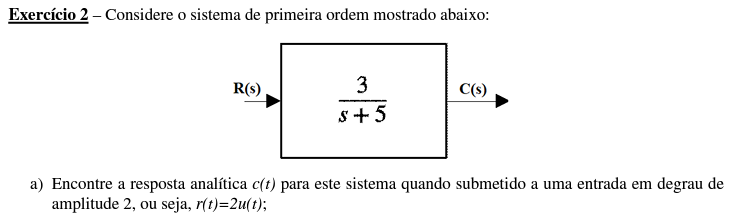


$$C\left(s\right)=\frac{2}{s}\frac{3}{5}\frac{5}{s+5}=\frac{6}{s\left(s+5\right)}=\frac{\mathrm{k1}}{s}+\frac{\mathrm{k2}}{s+5}=\frac{\frac{6}{5}}{s}-\frac{\frac{6}{5}}{s+5}=\frac{6}{5}\left(\frac{1}{s}-\frac{1}{s+5}\right)$$


Passando para o domínio do tempo, temos:


$$c\left(t\right)=\frac{6}{5}\left(1-e^{-5t} \right)\;\;\;\;\;\;b=2\;\;\;\;\;\;\;\;\;\;\;\;\;k=\frac{3}{5}$$


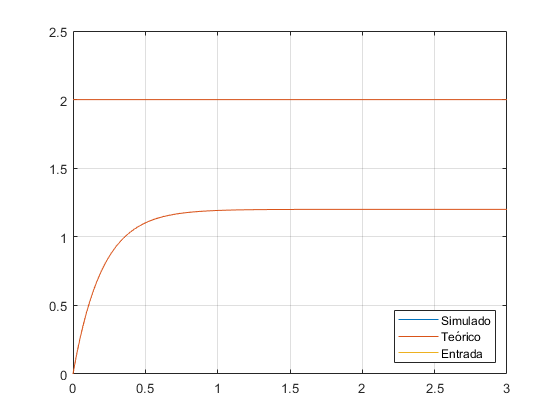

b = 2;
k = 3/5;
num = 3;
den = [1 5];
t = 0:0.01:3;
simu = b*step(num,den,t);
teo = b*k*(1-exp(-5*t));
input = b*ones(length(t));


plot(t,simu,t,teo,t,input);
grid on;
legend('Simulado', 'Teórico', 'Entrada', 'location', 'southeast');
axis([-inf +inf -inf 2.5])

A analisarmos o gráfico, percebe-se a curva teórica e simulada são identicas, logo, podemos afirmar que o modelo teórico realizado no item anterior esta correto. 

O teorema do valor final é dada pela seguinte equação:


$$c\left(\infty \right)=\mathrm{lim}\;\mathrm{sC}\left(s\right)|_{s\to 0} =\frac{6}{5}$$


Logo, temos que o valor de estabilização da saída em regime permanente é $c\left(\infty \right)=\frac{6}{5}=1,2$

Se compararmos esse valor com o valor obtido no gráfico, percebe-se que são identicos.

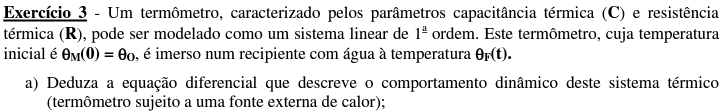

Temos que a EDO que rege o comportamento do sistema é dado pela seguinte equação:


$$\frac{d\theta \;}{\mathrm{dt}}=-a\left(\theta -\theta {\;}_m \right),\;\;\;\theta \left(0\right)=\theta_0$$



$$\begin{array}{l}
\frac{d\theta \;}{\theta -\theta {\;}_m }=-\mathrm{adt}\\
\int \frac{d\theta \;}{\theta -\theta {\;}_m }=-\int \mathrm{adt}\;\\
\mathrm{ln}\left(\theta -\theta {\;}_m \right)=-\mathrm{at}+c\\
\theta \left(t\right)-\theta {\;}_m =e^{-\mathrm{at}+c} \\
\theta \left(t\right)=e^{-\mathrm{at}+c} +\theta_m \;\;\;\;\;\;\;\;\;\;C=e^c \\
\theta \left(t\right)={\mathrm{Ce}}^{-\mathrm{at}} +\theta_m 
\end{array}$$


Aplicando a condição inicial, temos:


$$\begin{array}{l}
\theta_0 =C+\theta_m \\
C=\theta_0 -\theta_m 
\end{array}$$


Assim, encontrarmos a solução particular da EDO.


$$\theta \left(t\right)={\left(\theta_0 -\theta_m \right)e}^{-\mathrm{at}} +\theta_m$$


Para encontrarmos a função transferencia, utilizamos a equação do item anterior na sua forma diferencial


$$\frac{d\theta \;}{\mathrm{dt}}=-a\left(\theta -\theta {\;}_m \right)$$


Fazendo a transformada de Laplace e rearranjando os termos, temos:


$$\frac{\theta \left(s\right)}{\theta_m \left(s\right)}=\frac{a}{s+a}$$
                     

No tempo, com uma entrada degrau, temos a seguinte equação:


$$\theta \left(t\right)={\left(\theta_0 -\theta_m \right)e}^{-\mathrm{at}} +\theta_m$$


Sabendo que $\theta_0 =25$ e $\theta_m =55$, temos:


$$\theta \left(t\right)={-30e}^{-\mathrm{at}} +55$$


Para determinarmos a constante de temperatura, primeiro determinamos o valor de a. Para isso, aplicarmos um ponto conhecido na função.


$$\theta \left(3\right)=50\to 50={-30e}^{-3a} +55\to a=597,25\times {10}^{-3}$$


Posto isso, encontramos $\tau \;$pela seguinte relação:


$$\tau =\frac{1}{a}\to \tau =1,67$$


Logo, temos:


$$\theta \left(t\right)={55-30e}^{-\frac{t}{1,67}}$$


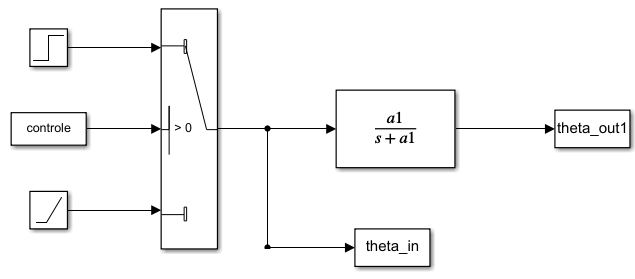

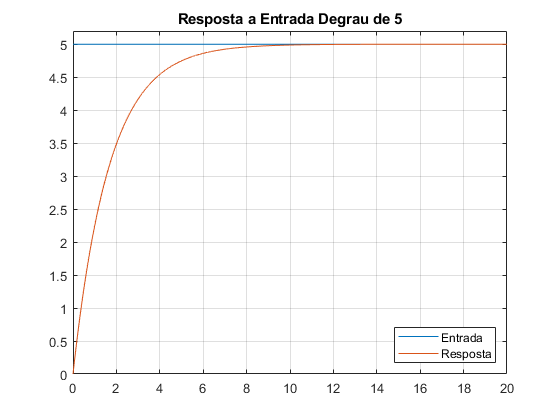

a1 = 597.25e-3;
controle = 1;
r = 5;
sim('exercicio1.slx');

plot(t,theta_in,t,theta_out1);
grid on;
legend('Entrada', 'Resposta', 'location', 'southeast');
axis([-inf 20 -inf theta_out1(end)+0.2]);
title('Resposta a Entrada Degrau de 5');

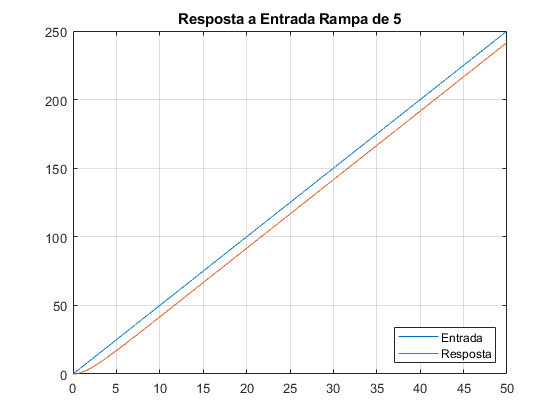

a = 597.25e-3;
controle = -1;
r = 5;
sim('exercicio1.slx');

plot(t,theta_in,t,theta_out);
grid on;
legend('Entrada', 'Resposta', 'location', 'southeast');
axis([-inf +inf -inf +inf]);
title('Resposta a Entrada Rampa de 5');

Se observarmos o gráfico da resposta a entrada degrau 5, é possível perceber que o sistema se estabiliza convergindo para a entrada, isto é, $k=1$.

Logo, temos:


$$\frac{d\theta \;}{\mathrm{dt}}=-a\left(\theta -\theta {\;}_m \right)$$



$$6=-a\left(\theta -\theta {\;}_m \right)\;\;\;\;\;\;a=\frac{6}{\theta_m -\theta }=200\times {10}^{-3}$$



$$\theta \left(t\right)={-25e}^{-0,2t} +55$$


Feito isso, motamos o seguinte simulink.

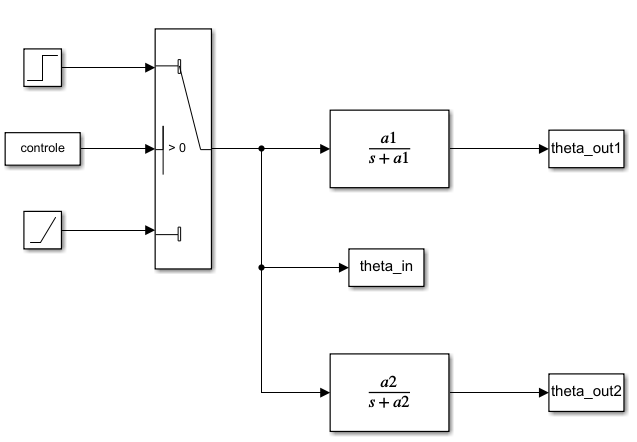

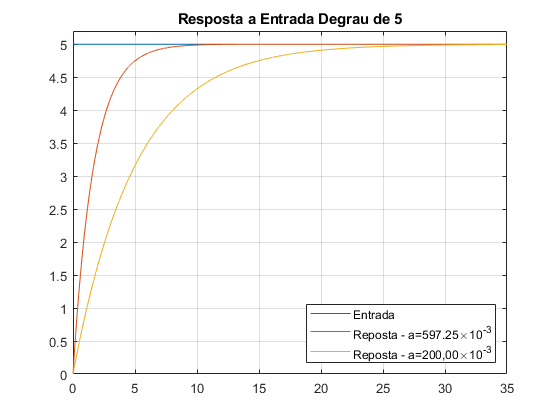

a1 = 597.25e-3;
a2 = 0.2;
controle = 1;
r = 5;
sim('exercicio1.slx');

plot(t,theta_in,t,theta_out1,t,theta_out2);
grid on;
legend('Entrada', 'Reposta - a=597.25\times10^{-3}', 'Reposta - a=200,00\times10^{-3}', 'location', 'southeast');
axis([-inf 35 -inf theta_out1(end)+0.2]);
title('Resposta a Entrada Degrau de 5');

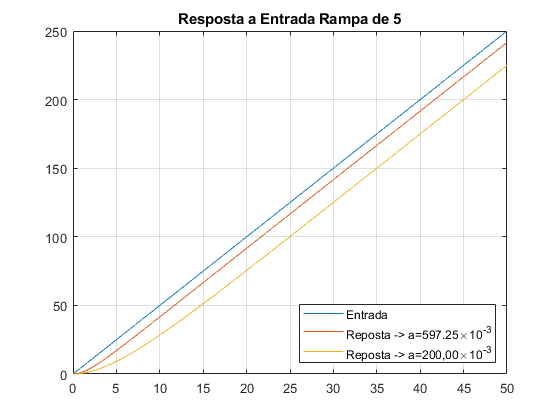

a1 = 597.25e-3;
a2 = 0.2;
controle = -1;
r = 5;
sim('exercicio1.slx');

plot(t,theta_in,t,theta_out1,t,theta_out2);
grid on;
legend('Entrada', 'Reposta -> a=597.25\times10^{-3}', 'Reposta -> a=200,00\times10^{-3}', 'location', 'southeast');
axis([-inf +inf -inf +inf]);
title('Resposta a Entrada Rampa de 5');

e_d = abs(theta_out1(end)-theta_out2(end))

e_d = 16.6272

erro = abs(theta_out1(end)-theta_out2(end))/theta_out1(end)*100

erro = 6.8813

Analisando o gráfico e utilizando o matlab, temos o erro entre as duas respostas:


$$\mathrm{erro}=\theta_1 -\theta_2 =16,63$$


Podemos também calcular o erro percentual:


$$\mathrm{erro}=\frac{|\theta_1 -\theta_2 |}{\theta_1 }\times 100=6,88%$$
